# k-space analysis of PEC waveguide

theta_in = 10*pi/180;       % rad
theta_out= 70*pi/180;       % rad

lambda = 1;                 % lambda
Lambda = lambda/abs(sin(theta_in)-sin(theta_out));  % lambda

eta = 1;                    % eta
k = 2*pi/lambda;              % 1/lambda
E0 = 1;                     % E0

NumLayers = 2;

phi0 = -k*Lambda*sin(theta_in);  %rad

reff = 6.35e-4;         % lambda for f = 10 GHz
MaxSizeLayer=lambda;

optimTimes = 500;
Norder=40;

% Hs =  [-0.5 ;-0.25]*lambda;
% Ds =  [0 ;0]*lambda;
% Zs =  [1e5 ; 1e4j]* eta;

Hs =  HsResults;
Ds =  DsResults;
Zs =  ZsResults;

resultion = 1000;
ky = linspace(0,1.5,resultion)*k;
H = linspace(1.1*max(abs(Hs)),4*lambda,resultion+1);

detA = zeros(resultion,resultion+1);
for Kyindex = 1:resultion
    for Hindex = 1:resultion+1
        detA(Kyindex,Hindex) = detCurrentMatrixKyH(k,ky(Kyindex),reff,Lambda,eta,Norder,Hs,Ds,Zs,H(Hindex));
    end 
end

## ploting

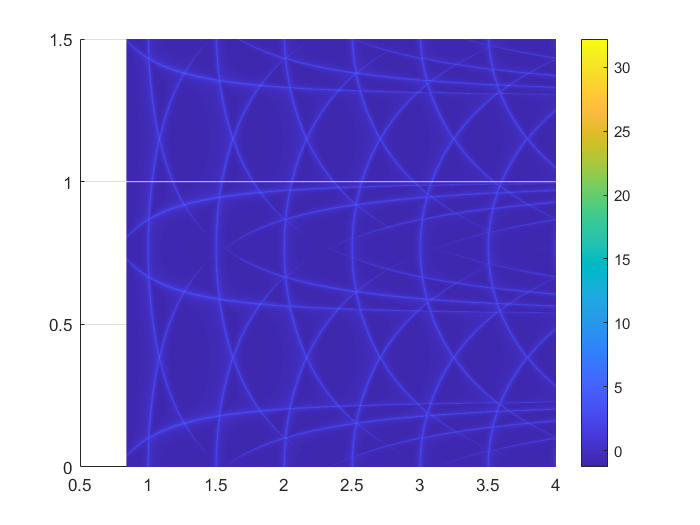


figure;
s = surf(H,ky/k,log(abs(detA))); s.EdgeColor='none'; colorbar; view([0 90]);

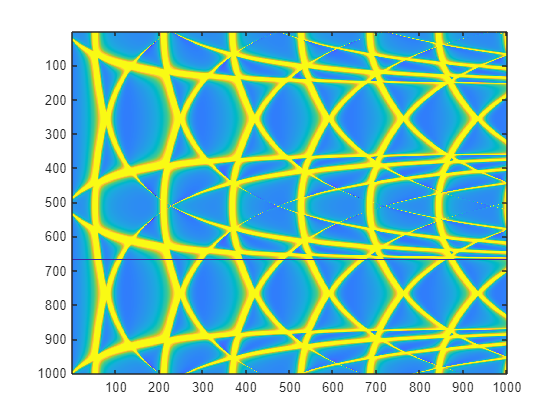

imagesc(log(abs(detA)),[min(log(abs(detA(:)))) -0.01]); 

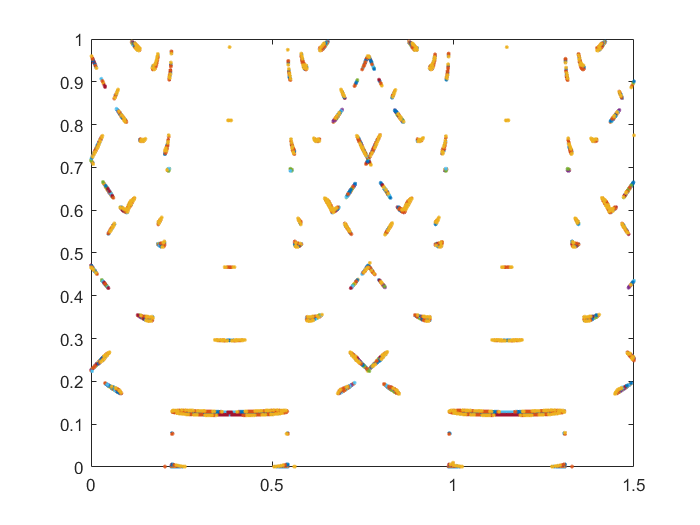

[~,indecis]=sort(abs(detA),2);
figure;
plot(ky/k,indecis(:,1:10)/resultion,'.');

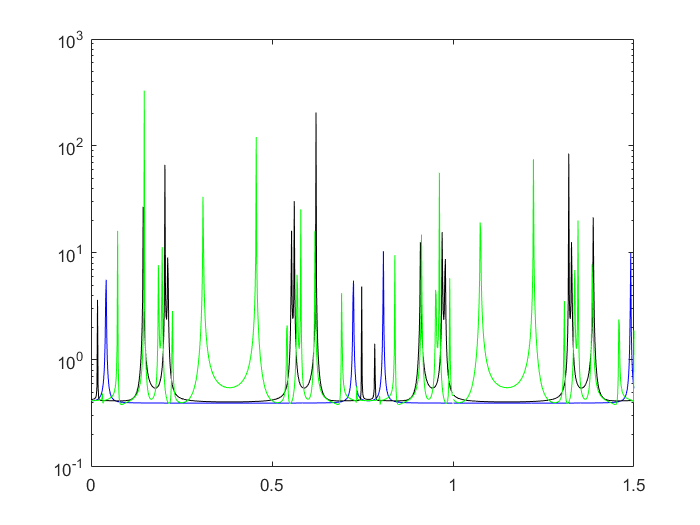

figure;
grid on;
semilogy(ky/k,abs(detA(:,3)),'b',ky/k,abs(detA(:,500)),'k',ky/k,abs(detA(:,900)),'g');

## Peak Anlysis

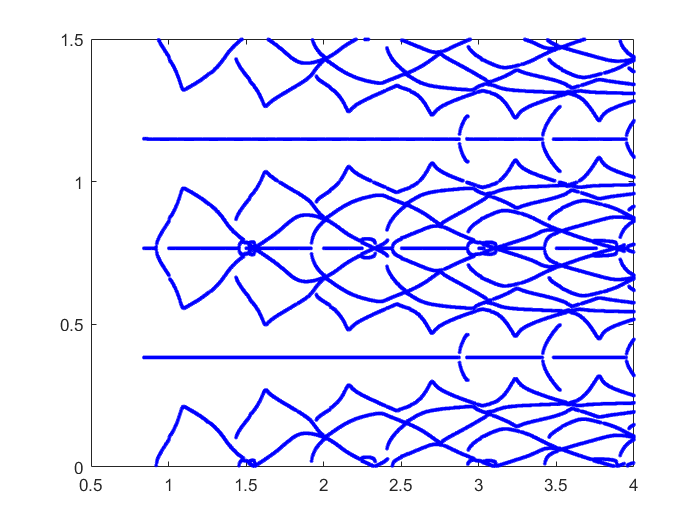

PeaksLocation = zeros(size(detA))./zeros(size(detA));
Allvalues = zeros(size(detA))./zeros(size(detA));
for Hindex = 1:resultion+1
    data = log(abs(detA(:,Hindex)));
    [values,peaks] = findpeaks(-data);
    numOfPeaks(Hindex)=length(peaks);
    PeaksLocation(1:length(peaks),Hindex)=peaks;
    Allvalues(1:length(peaks),Hindex)=values;
    clear peacks valueas;
end
plot(H,PeacksLocation/resultion*1.5,'.b');

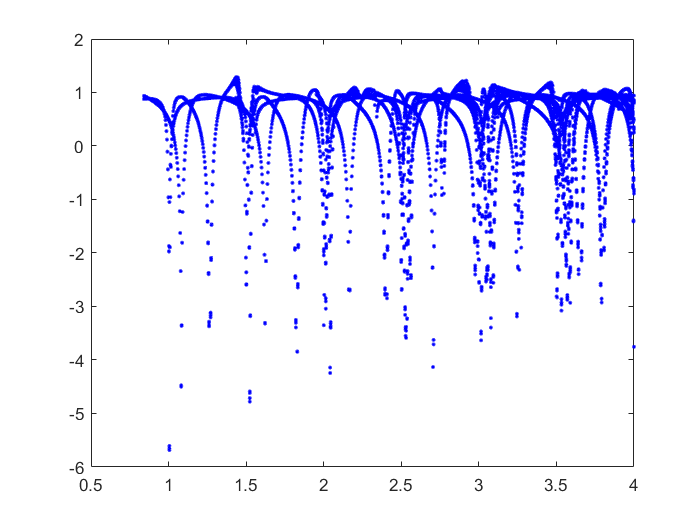

plot(H,Allvalues,'.b');

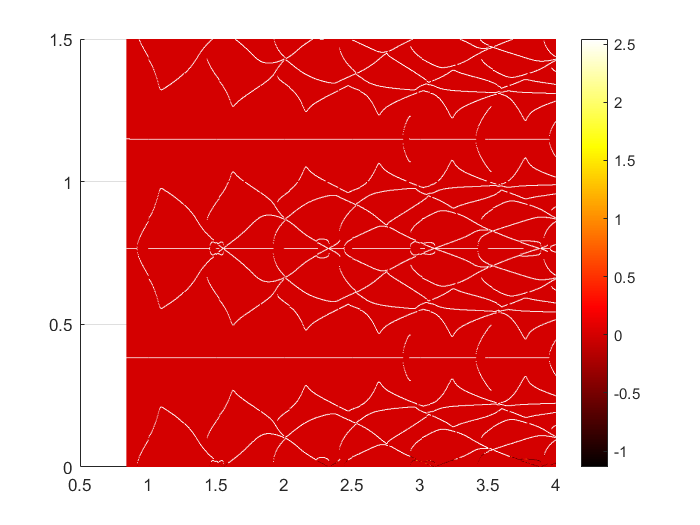

coloredPeaks = zeros(resultion,resultion+1);
for Hindex = 1: resultion
    for Kindex=1:numOfPeaks(Hindex)
        coloredPeaks(PeaksLocation(Kindex,Hindex),Hindex)=Allvalues(PeaksLocation(Kindex,Hindex),Hindex);
    end
end
figure;
s = surf(H,ky/k,-coloredPeaks); s.EdgeColor='none'; colorbar; view([0 90]);colormap hot;

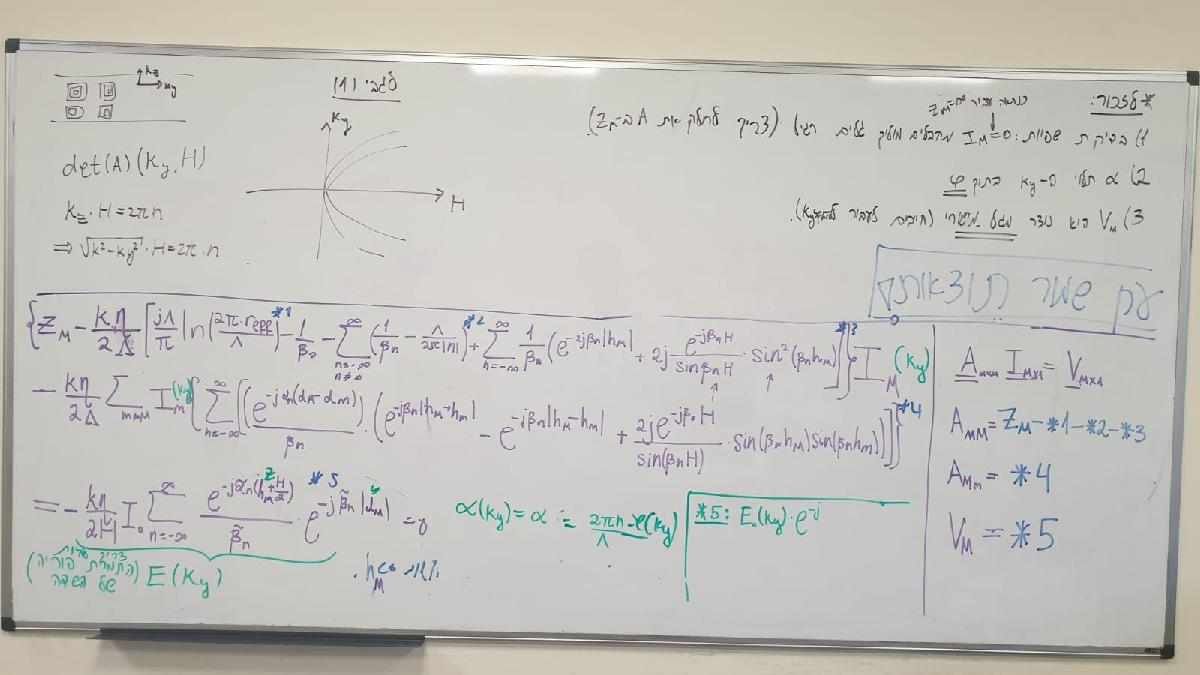

function [detMatrix] = detCurrentMatrixKyH(k,ky,reff,Lambda,eta,Norder,Hs,Ds,Zs,H)
    NumLayers = length(Hs);
    Matrix = zeros(NumLayers,NumLayers);
    phi = -ky*Lambda;
    for Mindex = 1:NumLayers
        for mindex = 1:NumLayers
            if (Mindex == mindex)
                Matrix(Mindex,mindex) = 1-k*eta/(2*Lambda*Zs(Mindex))*sumElemnts123(k,phi,Norder,reff,Lambda,Hs,H,Mindex);
            else
                Matrix(Mindex,mindex) = -k*eta/(2*Lambda*Zs(Mindex))*sumElemnts4(k,Lambda,phi,Norder,Hs,Ds,H,Mindex,mindex);
            end 
        end
    end
    detMatrix = det(Matrix);
end


function sumValue = sumElemnts123(k,phi,Norder,reff,Lambda,Hs,H,Mindex)
    nVec=(-Norder:Norder);
    nNoZero=[(-Norder:-1) (1:Norder)];
    [~,Betas] = calcAlphasBetas(k,Lambda,phi,nVec);
    [~,BetasNoZero] = calcAlphasBetas(k,Lambda,phi,nNoZero);
    element1 = 1j*Lambda/pi*log(2*pi*reff/Lambda) - 1/Betas(Norder+1);
    element2 = -sum( 1./BetasNoZero - Lambda/2/pi./abs(nNoZero),"all");
    element3 = sum(1./Betas.*(exp(-2j*Betas*abs(Hs(Mindex))) + ...
        2j*exp(-1j*Betas*H)./sin(Betas*H).*(sin(Betas*Hs(Mindex))).^2),"all");
    sumValue = element1+element2+element3;
end

function element4 = sumElemnts4(k,Lambda,phi,Norder,Hs,Ds,H,Mindex,mindex)
    nVec=(-Norder:Norder);
    [Alphas,Betas] = calcAlphasBetas(k,Lambda,phi,nVec);
    element4 = sum(exp(-1j*Alphas*(Ds(Mindex)-Ds(mindex)))./Betas.*...
        (exp(-1j*Betas*abs(Hs(Mindex)+Hs(mindex)))-exp(-1j*Betas*abs(Hs(Mindex)-Hs(mindex)))...
        +2j*exp(-1j*Betas*H)./sin(Betas*H).*sin(Betas.*Hs(Mindex)).*sin(Betas*Hs(mindex))),"all");
end

function [Alphas,Betas] = calcAlphasBetas(k,Lambda,phi,IndexVector)
    Alphas = (2*pi*IndexVector-phi)/Lambda;
    Betas  = conj(sqrt(k^2-Alphas.^2));
end